function F = EquilibriumEOM(x)

% EquilibriumEOM.mlx
%
% Static force and moment balance for equilibrium speed, pitch, and
% elevator deflection corresponding to steady, wings level flight at
% constant altitude.
%The 12 aircraft state eqations are solved for steady state, wings level,
%constant altitude. They are given below

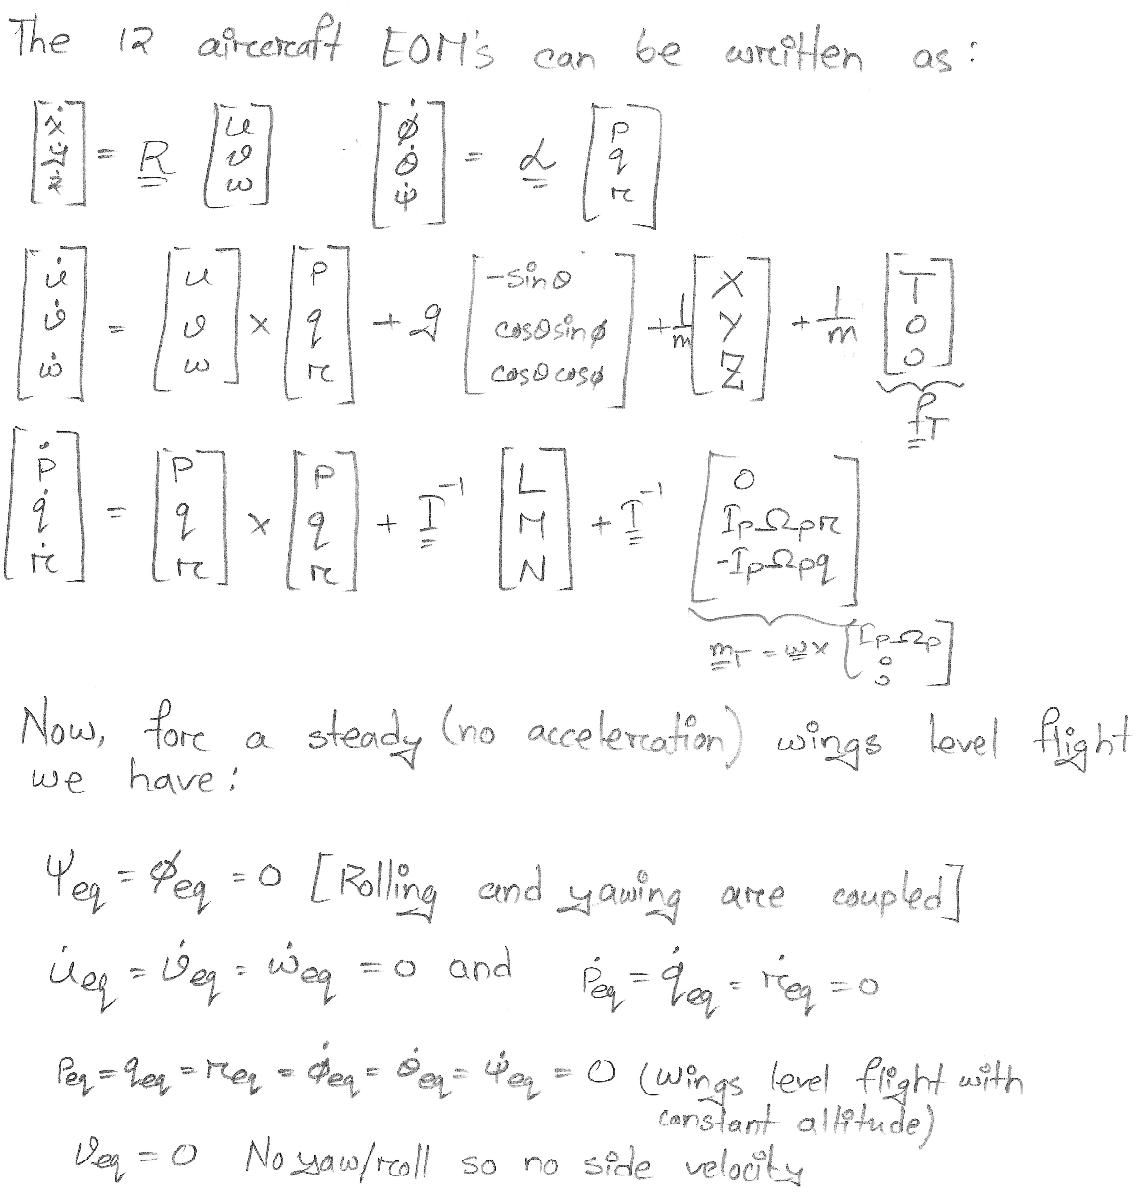

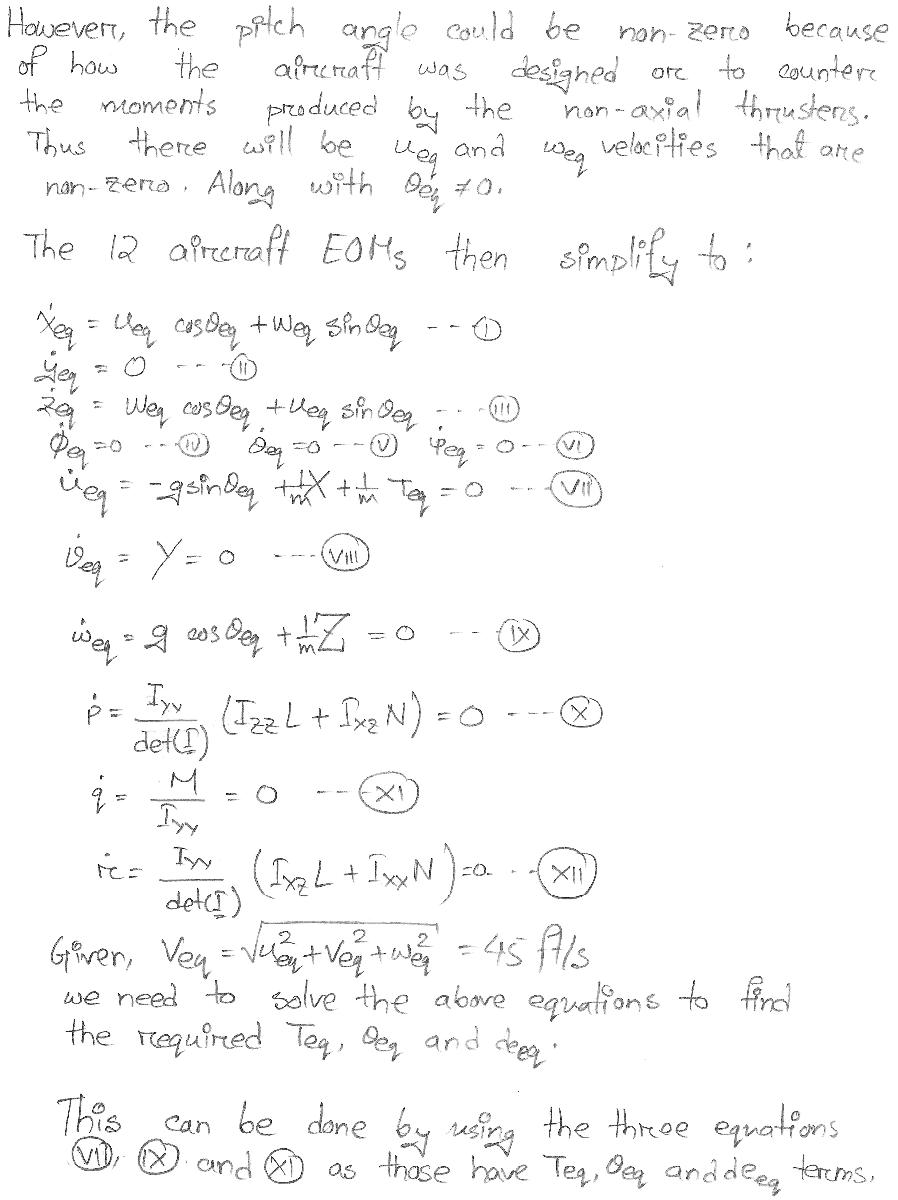


global rho S VEq m g Cxalpha Cxde Cxalpha2 Cx0 Czalpha Czde ...
    Czalpha2 Cz0 Cmalpha Cmde Cmalpha2 Cmalpha3 Cm0


% Initial values for equilibrium Thrust, Pitch and elevator deflection 
ThrustEq = x(1); % ft/s
thetaEq = x(2); % rad
deEq = x(3); % rad

%Assuming ambient wind gives alphaEq = thetaEq and qhatEq = 0 for wings
%level steady flight so Cm equation is modified a little
alphaEq = thetaEq;

% Nondimensional force and moment coefficients in equilibrium flight
Cx = Cxalpha*alphaEq + Cxde*deEq + Cxalpha2*(alphaEq^2) + Cx0; 
Cz = Czalpha*alphaEq + Czde*deEq + Czalpha2*(alphaEq^2) + Cz0;
Cm = Cmalpha*alphaEq + Cmde*deEq + Cmalpha2*(alphaEq^2) + ...
    Cmalpha3*(alphaEq^3) + Cm0;

% From Eqns VII, IX and XI above, non-dimensionalizing:
F(1) = Cx + (2/rho/S/VEq^2)*ThrustEq - (2/rho/S/VEq^2)*m*g*sin(thetaEq);
F(2) = Cz + (2/rho/S/VEq^2)*m*g*cos(thetaEq);
F(3) = Cm;

%This gives us three equations and three unknowns. Note: We could not use
%Cy, Cl and Cn equations because those only had a trivial solution of 0=0